%RGB to gray
img = rgb2gray(imread("images\pixelsize.jpg"));
[M,N] = size(img)

M = 1006

N = 1920

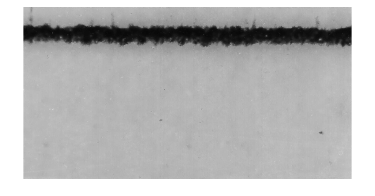

figure,imshow(img); imwrite(img,'images\pixelsize_gray.jpg');

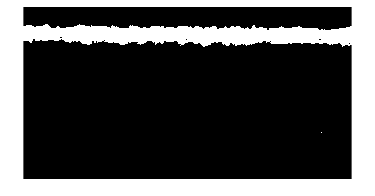


%Threshold
BW = img<90;
figure,imshow(BW); imwrite(BW,'images\pixelsize_thresh.jpg');

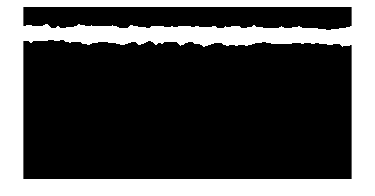


BW = bwareaopen(BW,200);
% figure, imshow(BW);
BW = imclose(BW,strel('disk', 20));
% figure, imshow(BW);
% BW = imopen(BW, true(9, 1));
figure, imshow(BW);imwrite(BW,'images\pixelsize_morph.jpg');

% imtool(BW)

% se = strel('rectangle',[70, N]);
% BW = imerode(BW,se);
% BW = imdilate(BW,se);
% figure, imshow(BW);


% [lrows, lcolumns] = find(BW(:,1:100));
% [rrows, rcolumns] = find(BW(:,N-100:N));
% topRow = min(rows);
% bottomRow = max(rows);

[rows,columns] = find(BW);
maxC=max(columns);
minC=min(columns);
maxR=max(rows);
minR=min(rows);

minY=zeros(1,N);
maxY=zeros(1,N);
 for i=1:N
    [rows,columns] = find(BW(:,i));
    minY(i)=min(rows);
    maxY(i)=max(rows);
 end


%Check camera alignement
lminmean=mean(minY(minC:100));
rminmean=mean(minY(maxC-100:maxC));
abs(lminmean-rminmean)

ans = 12.0060


%Find pixel size
minY_mean=mean(minY)

minY_mean = 117.3042

maxY_mean=mean(maxY)

maxY_mean = 212.5339

width=round(maxY_mean-minY_mean)

width = 95

pixelsize=0.076/width

pixelsize = 8.0000e-04



% props = regionprops(BW, 'BoundingBox');
% boundingBox = props.BoundingBox;
% xLeft = boundingBox(1);
% yTop = boundingBox(2);
% width = boundingBox(3)
% height = boundingBox(4)
% % Crop off the top, shaded portion of column headers,
% % which are known to be a fixed 29% of the height of the box.
% % Make a new bounding box.
% boundingBox2 = [xLeft, yTop, width, height];
% % Crop the image
% cropped_img = imcrop(img, boundingBox2);
% figure, imshow(cropped_img);